## Letter Dataset Analysis

### Initialise

clear;
clc;
clf;
close all;
% load 3 workspace class instances of LetterDatasetClass:
% - letterDatasetNotNormalised
% - letterDatasetNormalised (zscore)
% - letterDatasetNormalisedReducedFeatures
load letterDatasetClass.mat;

## Dataset Information: Original Data

- The attributes were loaded and are unchanged.

- letterDatasetNotNormalised.

- The p-value correlation uses a heatmap convenience class found in MATLAB's file exchange [4].

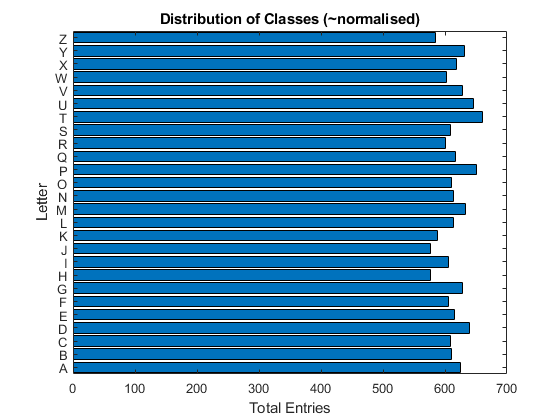

Summary of letter distribution:
Minimum examples per class: 577
Maximum examples per class: 661
Median number of examples per class: 613.5000


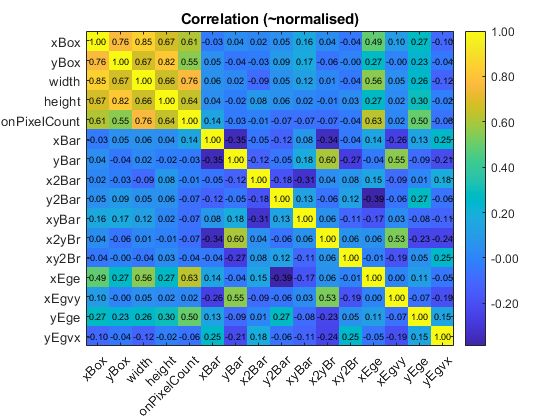

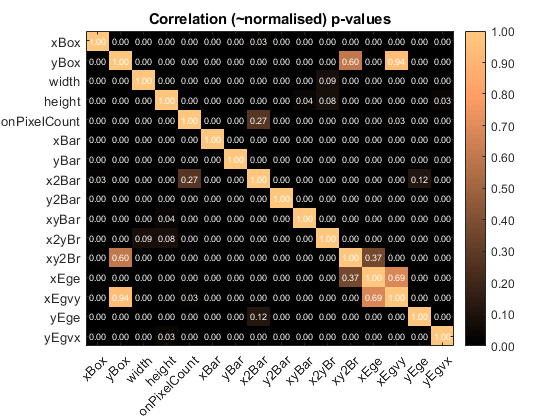

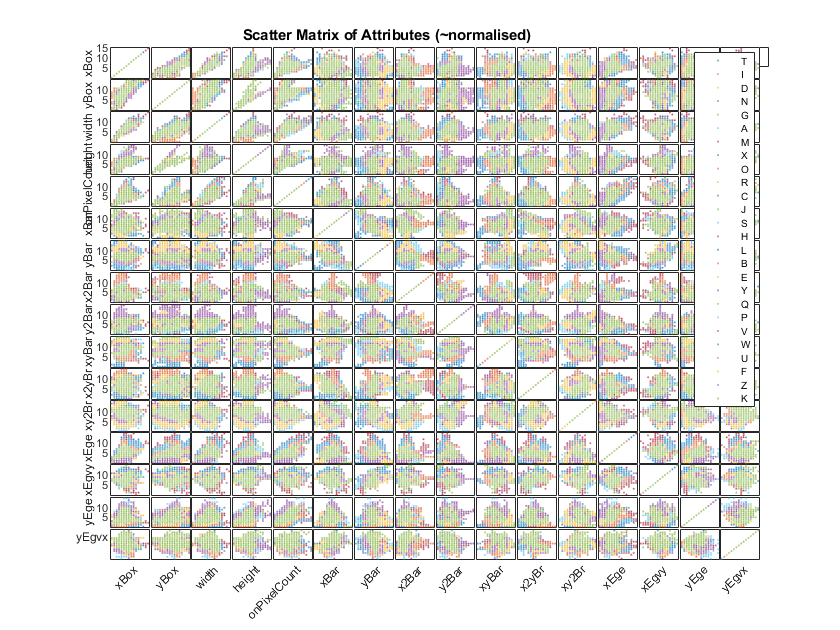

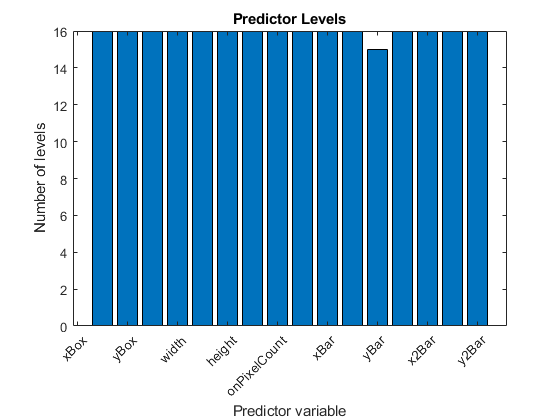

letterDatasetNotNormalised.displayDatasetPlots();

letterDatasetNormalised.displayDatasetInformation();

  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×16 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×17 table]
                trainTable: [16000×17 table]
                 testTable: [4000×17 table]
              isNormalised: 1
          isRemovedFeature: 0

Training Table Summary:

Variables:

    TargetAscii: 16000×1 cell array of character vectors

    xBox: 16000×1 double

        Values:

            Min         -2.1101
            Median    -0.015025
            Max          5.7463

    yBox: 16000×1 double

        Values:

            Min          -2.138
            Median    -0.012053
            Max        

## Dataset Information: attributes normalised

- The attributes are normalised using zscore normalization.

- letterDatasetNormalised.

- The p-value correlation uses a heatmap convenience class found in MATLAB's file exchange [4].

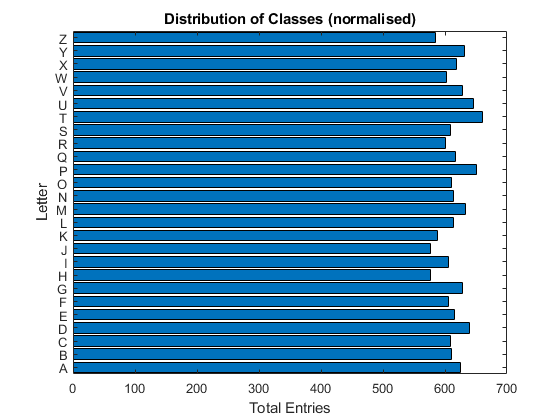

Summary of letter distribution:
Minimum examples per class: 577
Maximum examples per class: 661
Median number of examples per class: 613.5000


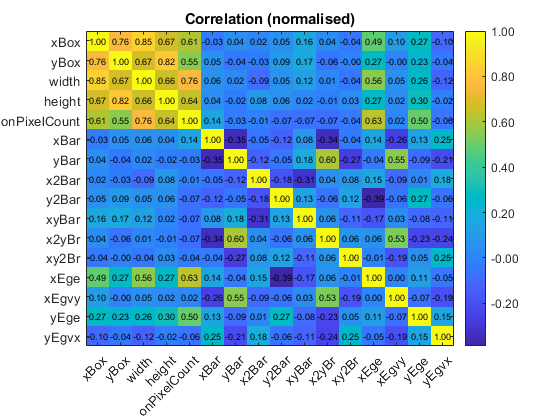

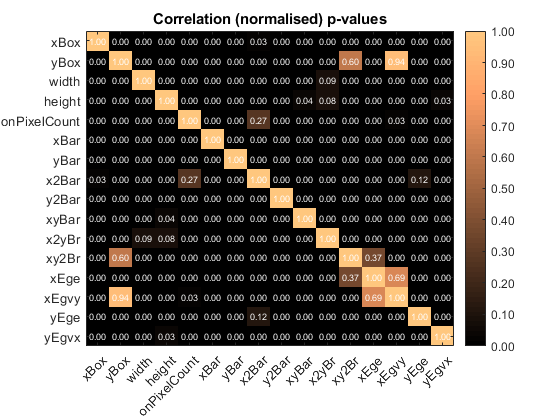

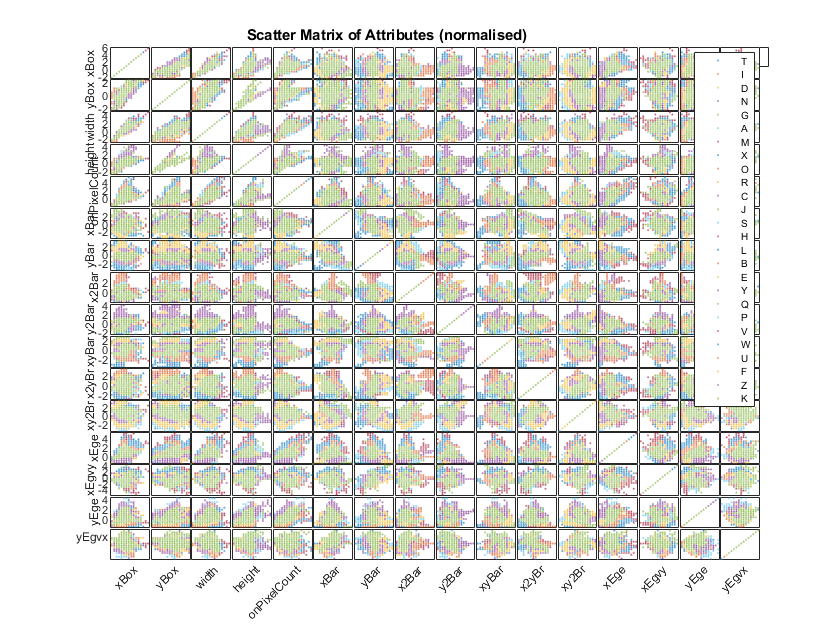

letterDatasetNormalised.displayDatasetPlots();

letterDatasetNormalised.displayDatasetInformation();

  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×16 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×17 table]
                trainTable: [16000×17 table]
                 testTable: [4000×17 table]
              isNormalised: 1
          isRemovedFeature: 0

Training Table Summary:

Variables:

    TargetAscii: 16000×1 cell array of character vectors

    xBox: 16000×1 double

        Values:

            Min         -2.1101
            Median    -0.015025
            Max          5.7463

    yBox: 16000×1 double

        Values:

            Min          -2.138
            Median    -0.012053
            Max        

## Dataset Information: attributes normalised, some features removed

- The attributes are normalised.

- letterDatasetNormalisedReducedFeatures.

- The p-value correlation uses a heatmap convenience class found in MATLAB's file exchange [4].

- The feature selection uses the filter approach, which is does not use the algorithm to do the feature selection, as done with the wrapper approach[3].

- More specifically the correlation of attributes is used as a filter approach. Bearing in mind that the goal is to compare machine two learning methods: Naive Bayes and Random Forest. Correlation is chosen over the other available filter approaches (entropy, information gain...) [3], as a way of reducing the time taken to successively train the model. This filtering method gives better performance for Naive Bayes [3].

- highly correlated attributes have been removed (xBox, yBox, width, height)

Summary of letter distribution:
Minimum examples per class: 577
Maximum examples per class: 661
Median number of examples per class: 613.5000


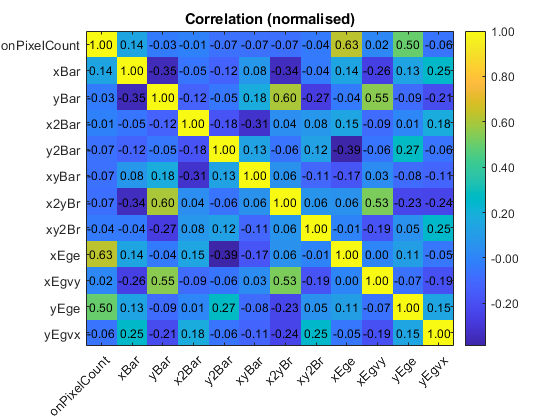

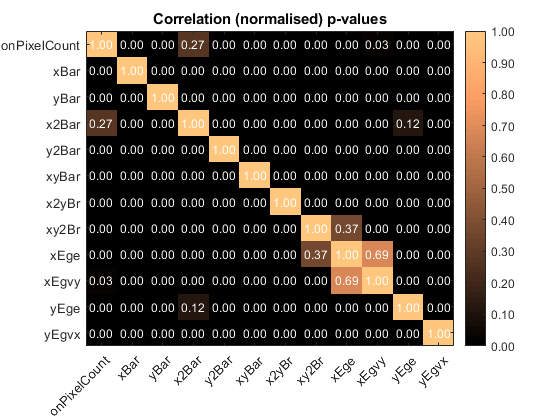

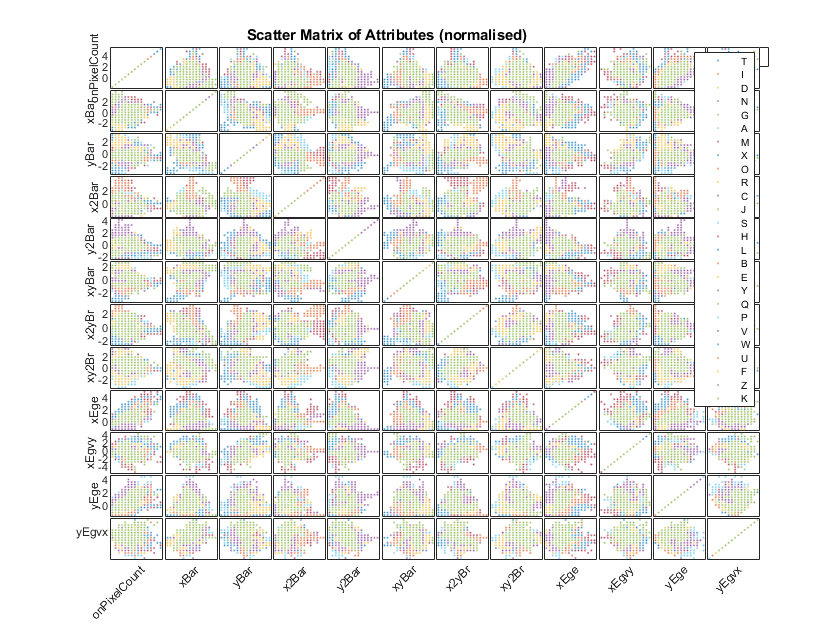

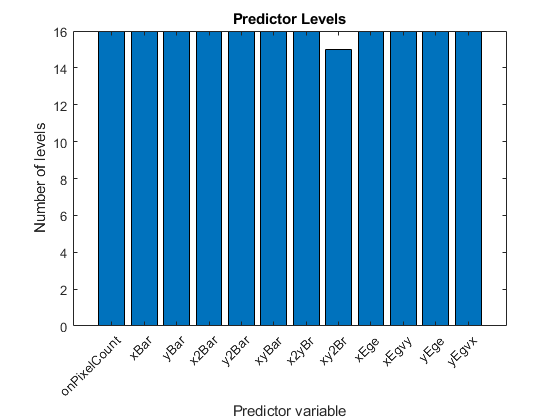

letterDatasetNormalisedReducedFeatures.displayDatasetPlots();

letterDatasetNormalisedReducedFeatures.displayDatasetInformation();

  LetterDatasetClass with properties:

           datasetFilePath: "Dataset/letter-recognition.csv"
         testSetProportion: 0.2000
                randomSeed: 1
                targetName: {'TargetAscii'}
              featureNames: {1×12 cell}
          validClassValues: [26×1 table]
    datasetContentsAsTable: [20000×13 table]
                trainTable: [16000×13 table]
                 testTable: [4000×13 table]
              isNormalised: 1
          isRemovedFeature: 1

Training Table Summary:

Variables:

    TargetAscii: 16000×1 cell array of character vectors

    onPixelCount: 16000×1 double

        Values:

            Min        -1.6025
            Median    -0.23125
            Max         5.2537

    xBar: 16000×1 double

        Values:

            Min        -3.3985
            Median    0.054728
            Max     

## Analysis Conclusions

- The dataset distribution of target examples can be treated as balanced (min examples per class 577, max 661).

- There is some strong correlation between attributes which are highly likely to be associated. The scatter matrix confirms this by showing a tendency to plot in a linear grouping. These highly correlated attributes are good candidates for removal, because there is no information gained by keeping them in the dataset [1]. The attributes are xBox, yBox, width, height.

- Once removed the correlation between attributes is better. Also the p-values correlations are low, which means no attributes are irrelevant to determining the class value (noise).

- three versions of the dataset are saved in letterDatasetClass.mat, for use in the method comparisons (Naive Bayes, Decision Tree, Random Forest).

## References

[1] I. Guyon and A. Elisseeff, “An Introduction to Variable and Feature Selection,” *J. Mach. Learn. Res.*, vol. 3, p. 26, 2003.

[2] Fery and Slate, "Letter Recognition Using Holland-Style Adaptive Classifiers", Machine Learning, 6, 161-182 (1991)  

[3] HAN LIU, MIHAELA COCEA, WEILI DING, "DECISION TREE LEARNING BASED FEATURE EVALUATION AND SELECTION FOR IMAGE CLASSIFICATION", Proceedings of the 2017 International Conference on Machine Learning and Cybernetics, Ningbo, China 9-12 July 2017.

[4] Ameya Deoras (2020). Customizable Heat Maps (https://www.mathworks.com/matlabcentral/fileexchange/24253-customizable-heat-maps), MATLAB Central File Exchange. Retrieved November 2, 2020.